# VD Workbench

%clear; %clf; % Remember to clear after importing a different file / making major changes!

% MODES
GTYPE = "IMU";      % Switches the accelerometer used for calculations
SPEEDMODE = "GPS";  % Switches the speed data used for calculations
DATATYPE = "LapsBeacon";   % Changes the lap finding and run trimming behavior 

% IMPORT
% Uncomment the first line for a GUI file select
% [filename, path] = uigetfile('*.csv', 'Select First MoTeC Output File');
filename = "Colin5LapAutocross.csv";
path = "./Data";
run = motecImport(filename, path);

% TRIM
if DATATYPE == "LapsBeacon"
    li = find(run.LapNumber > min(run.LapNumber) & run.LapNumber < max(run.LapNumber));
    run = run(li,:); % trim the original run variable
end

% HELPER VARIABLES 
[gLat, gLong, speed, time] = SetupVariables(run, GTYPE, SPEEDMODE);
car = FB2223();
lapZero = min(run.LapNumber) - 1; 
lapMax = max(run.LapNumber); 


## Calc Code

[UA, AA, WA] = UndersteerAngle(gLat,speed,run.SteeredAngle,car);

[TA, gMaxes, gThrottles] = ThrottleAcceptance(run, gLat) 

TA =    18.5634   74.0775   30.7044   83.0439    5.3163   35.7831   36.7561   36.6031   38.2598   25.0576   54.0762   35.8015    1.6080   33.8583   31.2468   54.3159   20.3169   43.4746   20.7857   28.6751   25.6923   44.3435   29.1275   36.6819


gMaxes =     2.4780    2.1410    2.0160    1.9580    1.8810    2.4900    2.3860    2.6200    2.5170    2.1710    2.4410    2.4580    1.9900    2.6670    1.9810    2.6530    2.4610    2.3600    2.6220    2.2040    2.6000    2.2010    2.2350    2.6280


gThrottles =     0.4600    1.5860    0.6190    1.6260    0.1000    0.8910    0.8770    0.9590    0.9630    0.5440    1.3200    0.8800    0.0320    0.9030    0.6190    1.4410    0.5000    1.0260    0.5450    0.6320    0.6680    0.9760    0.6510    0.9640



for i = 1:lapMax-lapZero
    [i1, i2] = LapBounds(run, lapZero, lapMax, i);
    
    Lap(i) = i;
    lapTimes(i) = time(i2) - time(i1);
    
    [UA1, AA1, WA1] = UndersteerAngle(gLat(i1:i2),speed(i1:i2),run.SteeredAngle(i1:i2),car);
    avgUA(i) = mean(UA1);
    
    [GO, GB, GA, GC, GAero] = GripSubsets(gLat(i1:i2), gLong(i1:i2), speed(i1:i2));
    avgGO(i) = mean(GO);
    avgGB(i) = mean(abs(GB));
    avgGA(i) = mean(GA);
    avgGC(i) = mean(GC);
    avgGAero(i) = mean(GAero);
end

OverallGrips = GripSubsets(gLat, gLong, speed);


## Plotting Code

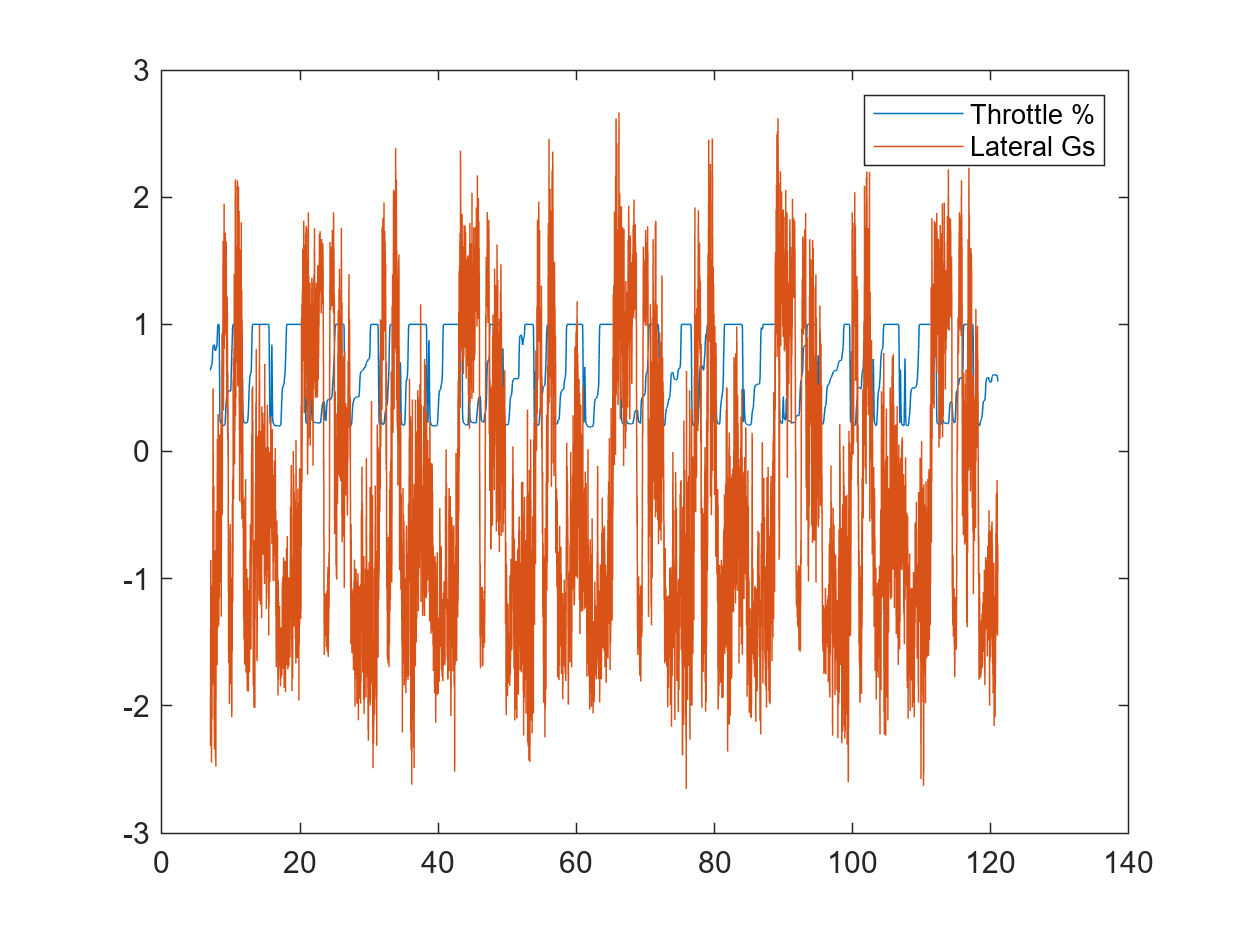

clf;

figure
plot(time,run.ThrottlePos ./ 100, time,gLat)
legend("Throttle %", "Lateral Gs")
title("")

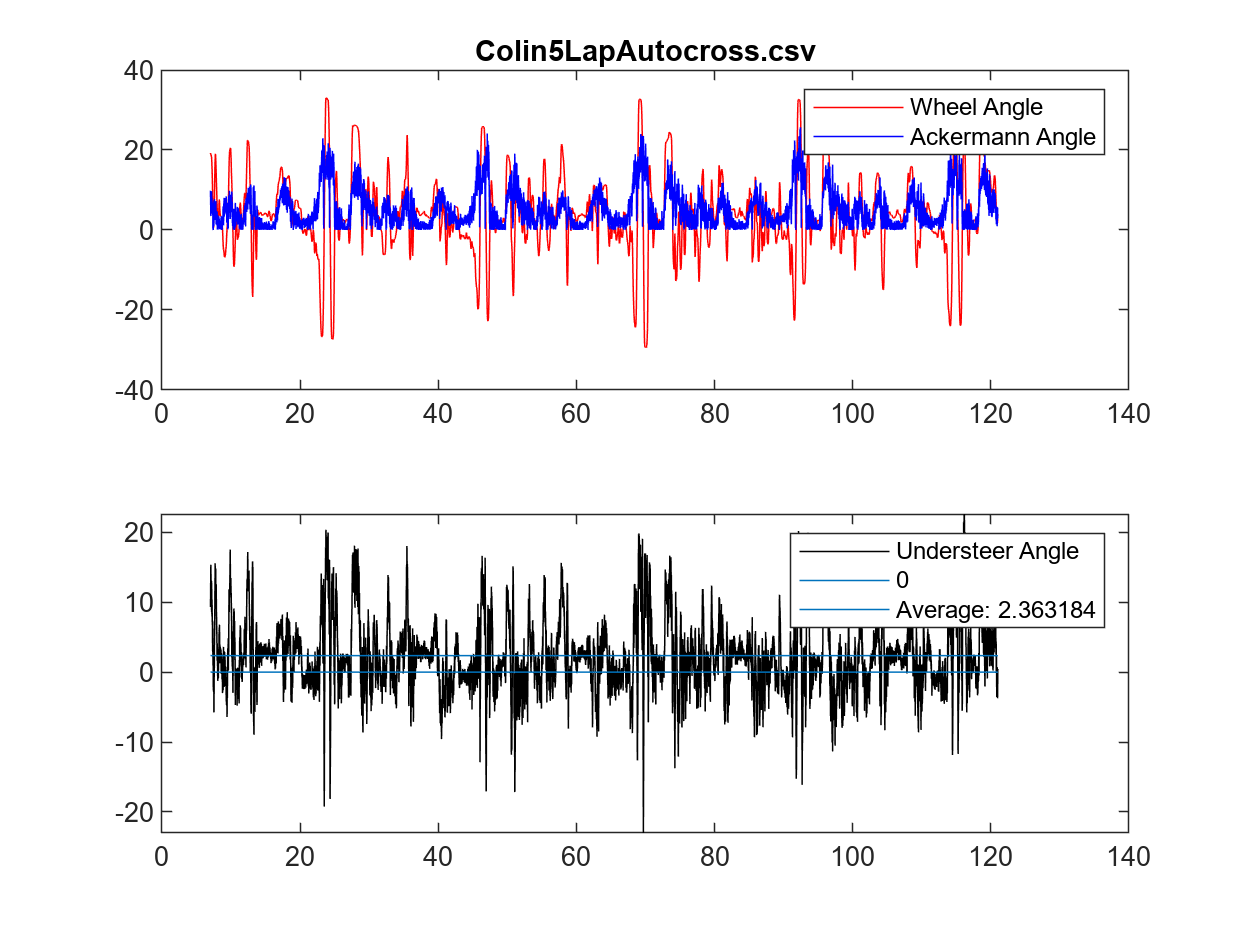


figure
UndersteerDisplay(filename, time, WA, AA, UA);

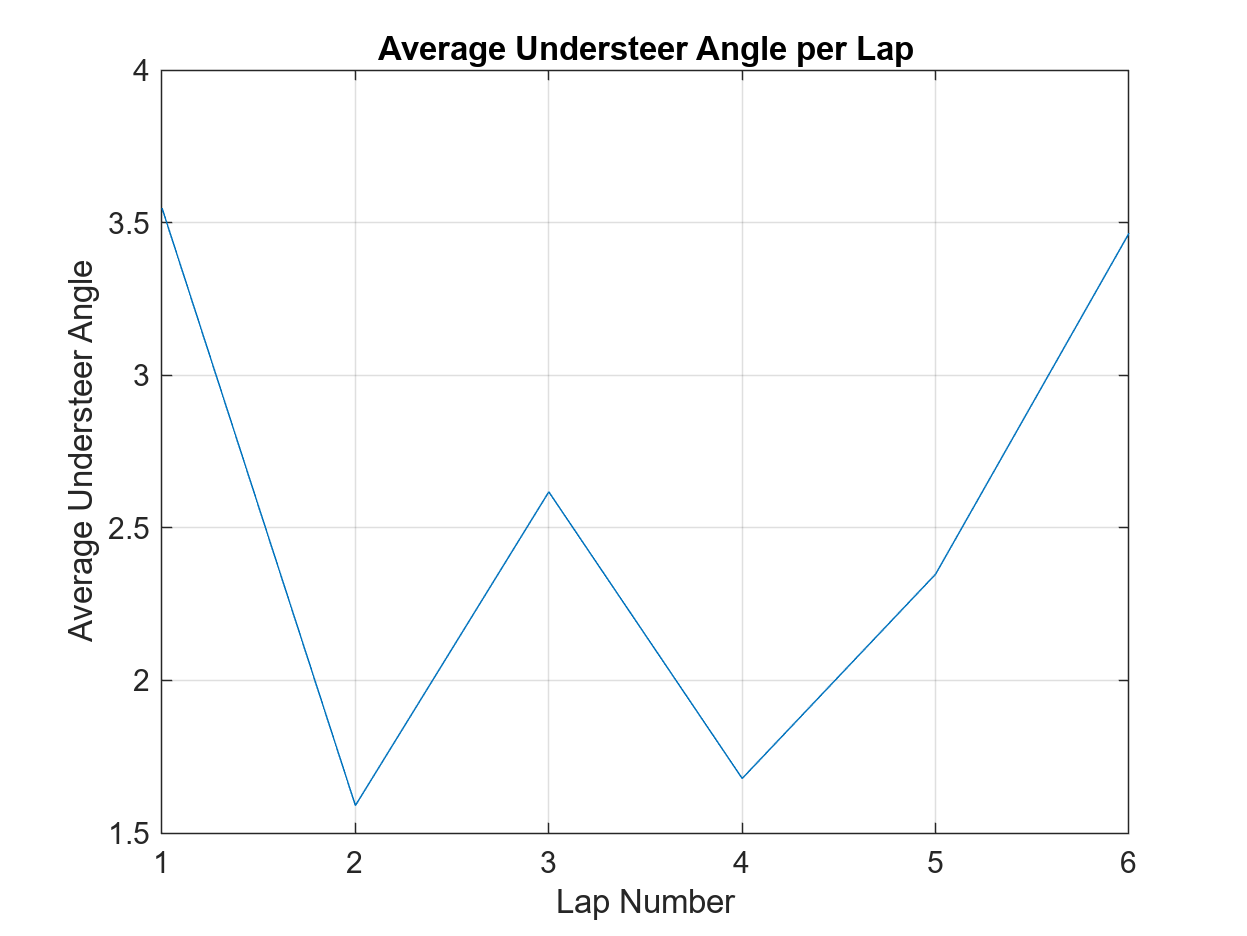


figure
plot(Lap, avgUA); grid on; title('Average Understeer Angle per Lap'); 
xlabel('Lap Number'); ylabel('Average Understeer Angle')

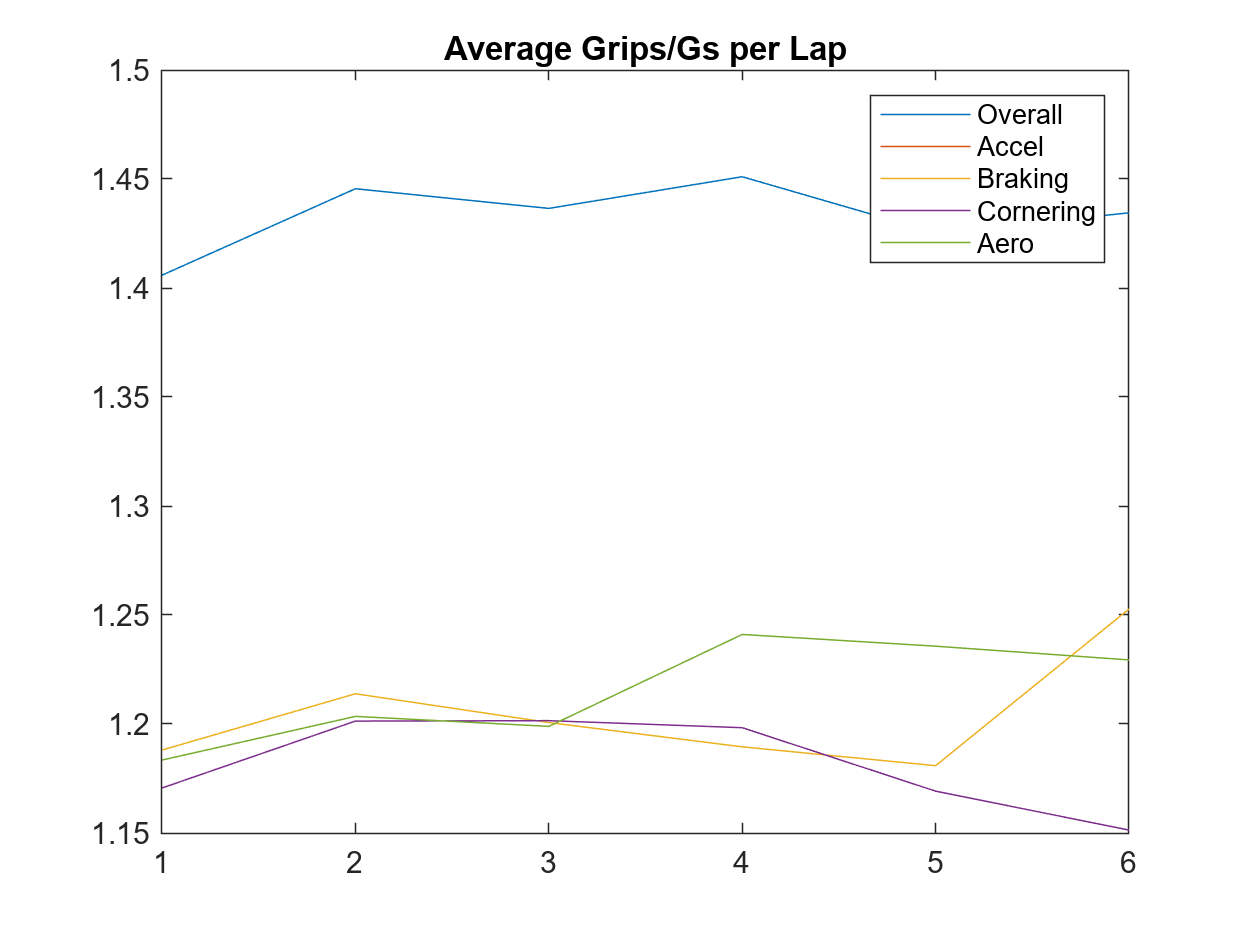


figure
plot(Lap, avgGO, ...
    Lap, avgGA, ...
    Lap, avgGB, ...
    Lap, avgGC, ...
    Lap, avgGAero)
title("Average Grips/Gs per Lap")
legend('Overall','Accel','Braking','Cornering','Aero')

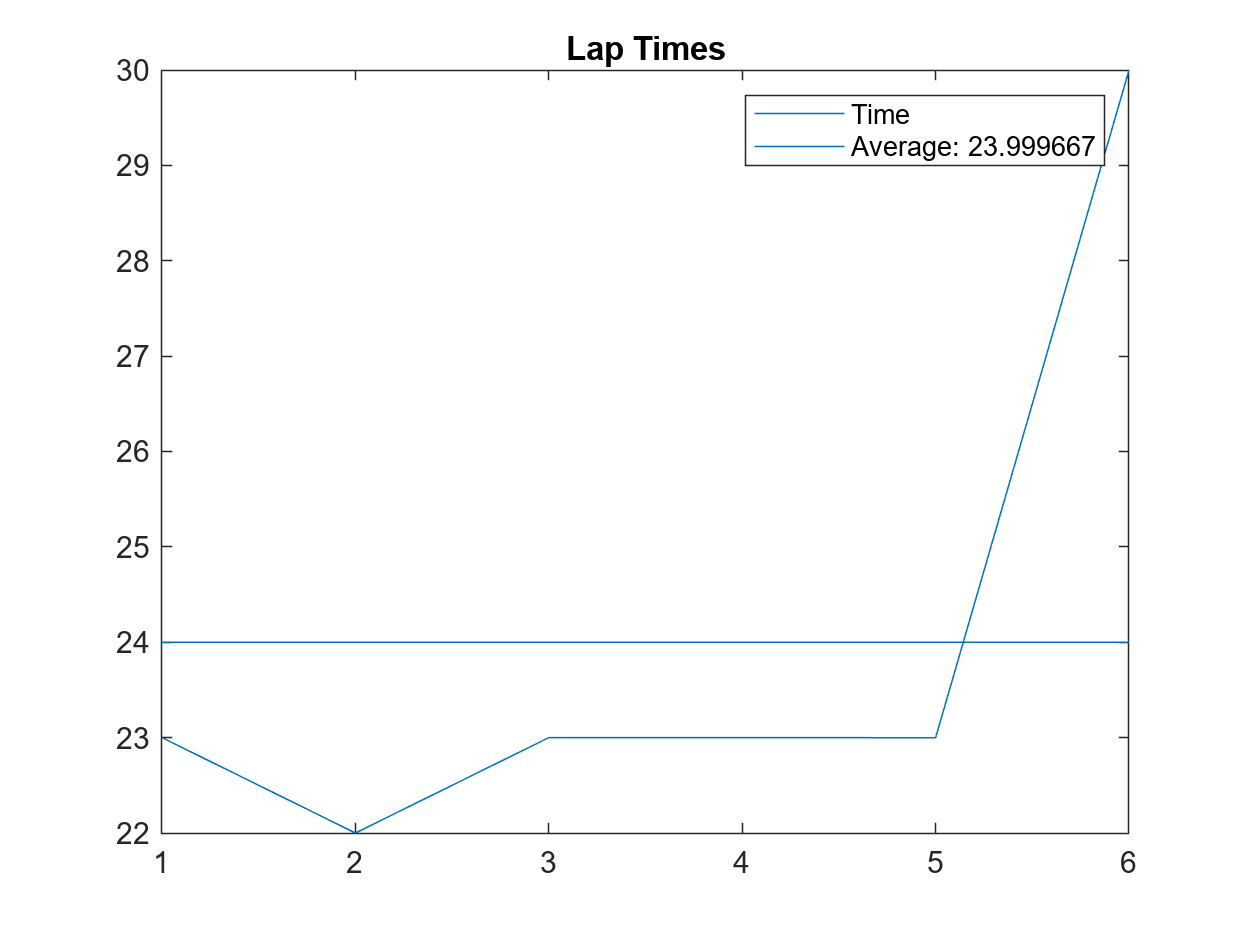


figure
plot(Lap,lapTimes)
title("Lap Times")
line([1 max(Lap)], [mean(lapTimes) mean(lapTimes)])
legend('Time', sprintf('Average: %f', mean(lapTimes)))

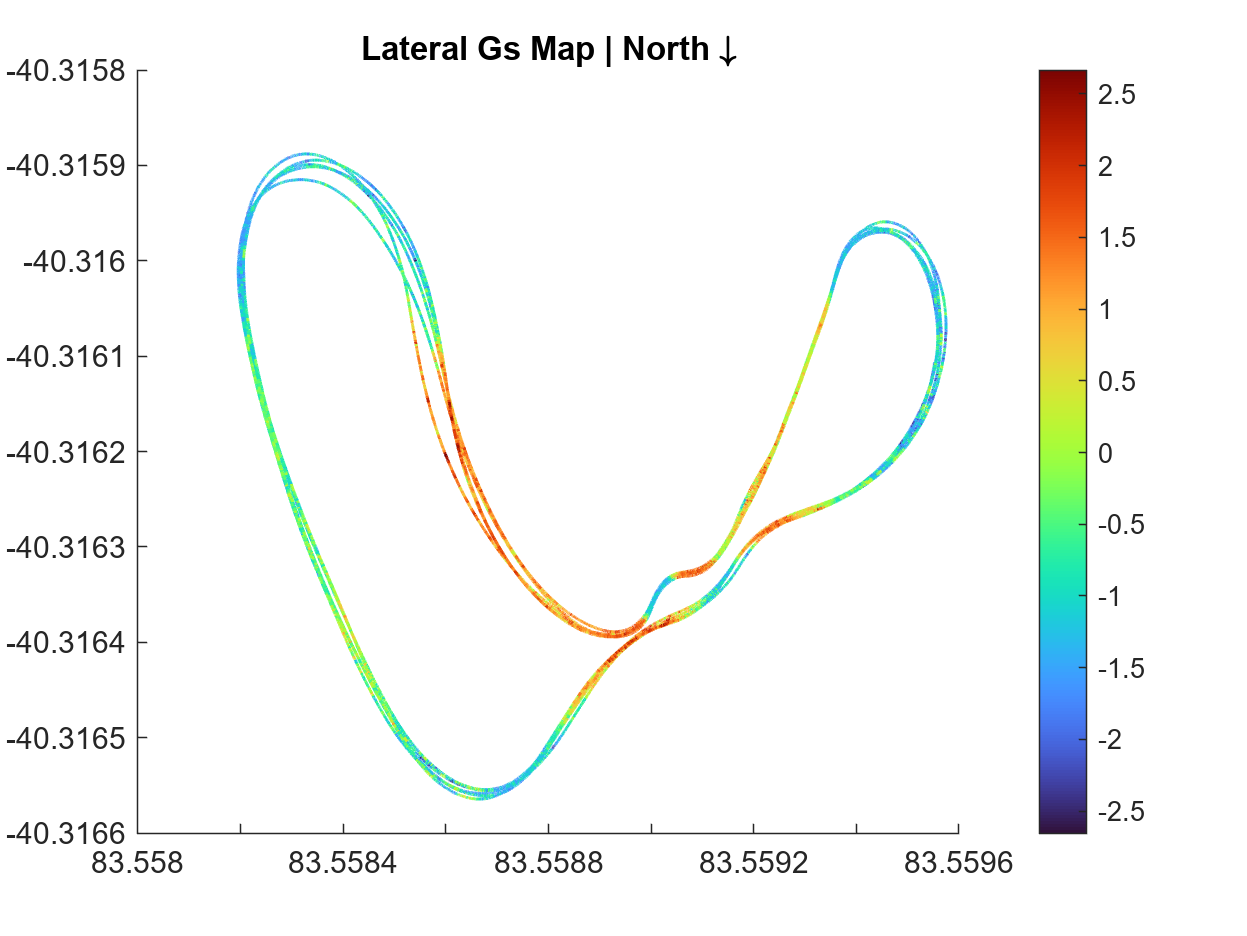


figure 
TrackDisplay(-run.GPSLongitude, -run.GPSLatitude, gLat)
title("Lateral Gs Map | North \downarrow")